# `Lista 4`

`Hubert Jackowski`

## `Układ RLC`

`Obwód RLC to obwód elektryczny składający się z rezystora (R), cewki indukcyjnej (L) i kondensatora (C), połączonych szeregowo lub równolegle. Nazwa obwodu pochodzi od liter używanych do oznaczenia elementów składowych tego obwodu, przy czym kolejność elementów może różnić się w zależności od typu RLC. `

`Model obwodu jest oscylatorem harmonicznym prądu i rezonuje w sposób podobny do obwodu LC. Wprowadzenie rezystora zwiększa zanik tych oscylacji, co jest również znane jako tłumienie. W praktyce obwody LC również zachowują się jak obwód RLC, ponieważ pewien opór jest nieunikniony, nawet jeśli rezystor nie jest specjalnie uwzględniony jako element - obwód również ma swój opór.`

#### `MODEL`

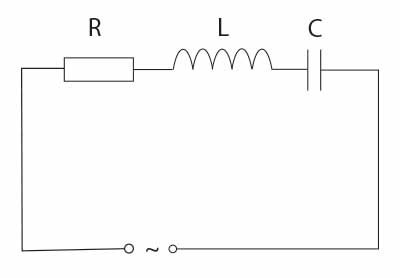

`Figure 1: Fizyczny i matematyczny model układu RLC`

def RLC(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float):
    t = sp.symbols('t')
    q = sp.Function('q')(t)
    i = sp.Function('i')(t)

    eq1 = sp.Eq(q.diff(t), i)
    eq2 = sp.Eq(L * i.diff(t) + R * i + q / C, A * sp.cos(Omega * t))

    solution = sp.dsolve((eq1, eq2), ics={q.subs(t, 0): q0, i.subs(t, 0): i0})

    return solution

def simulate(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float, dt: float, time: float):
    equations: list[sp.Eq] = DynamicModel.SympySolver.RLC(q0, i0, R, C, L, A, Omega)
    numberOfSteps = int(time / dt)
    systemEvolution = []
    for equation in equations:
        eqEvolution = []
        for step in range(numberOfSteps):
            eqEvolution.append(equation.rhs.subs("t", dt * step))
        systemEvolution.append(eqEvolution)
    return systemEvolution

`Figure 2: Realizacja modelu układu RLC za pomocą biblioteki sympy w języku Python`

def simulate(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float, dt: float,
             time: float):
    def _V(_t, a: float, omega: float):
        return a * np.cos(omega * _t)

    def _RLC(y, _t, _R, _L, _C):
        q, i = y

        dqdt = i
        didt = (1 / _L) * (_V(_t, A, Omega) - _R * i - q / _C)

        return [dqdt, didt]

    y0 = [q0, i0]
    t = np.arange(0.0, time, dt)
    solution = odeint(_RLC, y0, t, args=(R, L, C))
    return solution.T

`Figure 3: Realizacja modelu układu RLC za pomocą metody scipy.integrate.odeint w języku Python`

`ROZWIĄZANIE ANALITYCZNE`

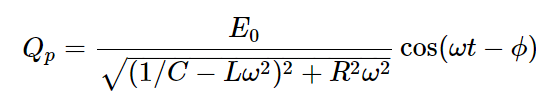

`Figure 4: Analityczne rozwiązanie układu równań różniczkowych opisujących obwód RLC`

`ŚREDNI BŁĄD APROKSYMACJI`

`Figure 5: Matematyczny wzór średniego błędu bezwzględnego`

`Figure 6: Matematyczny wzór średniego błędu kwadratowego`

#### `OBSERWACJE`

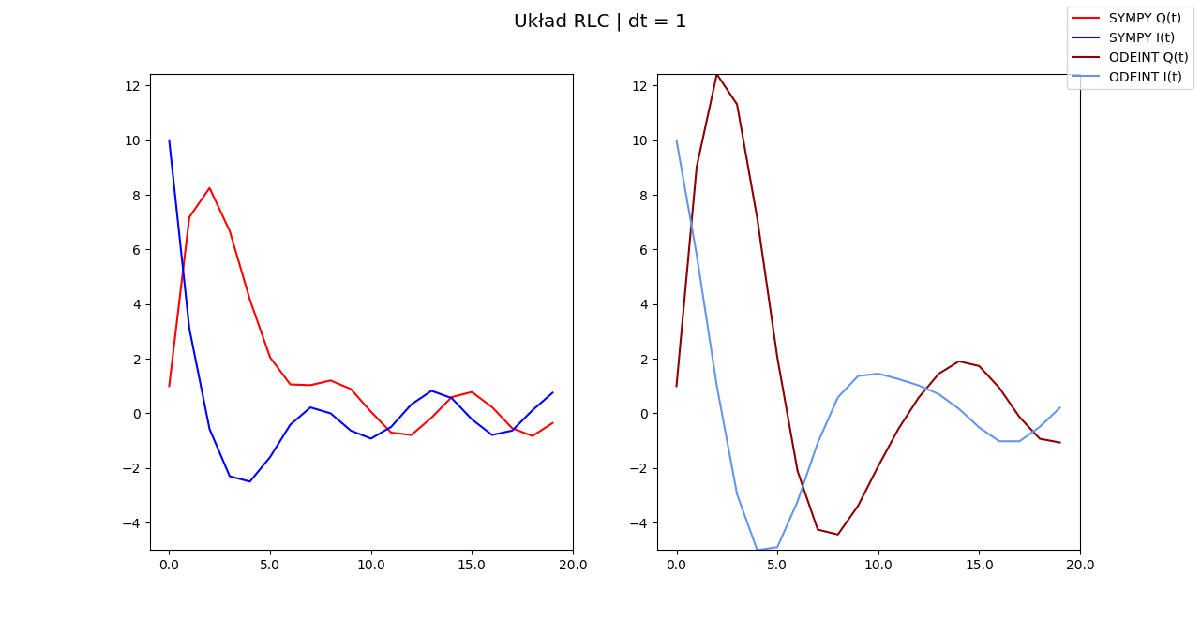

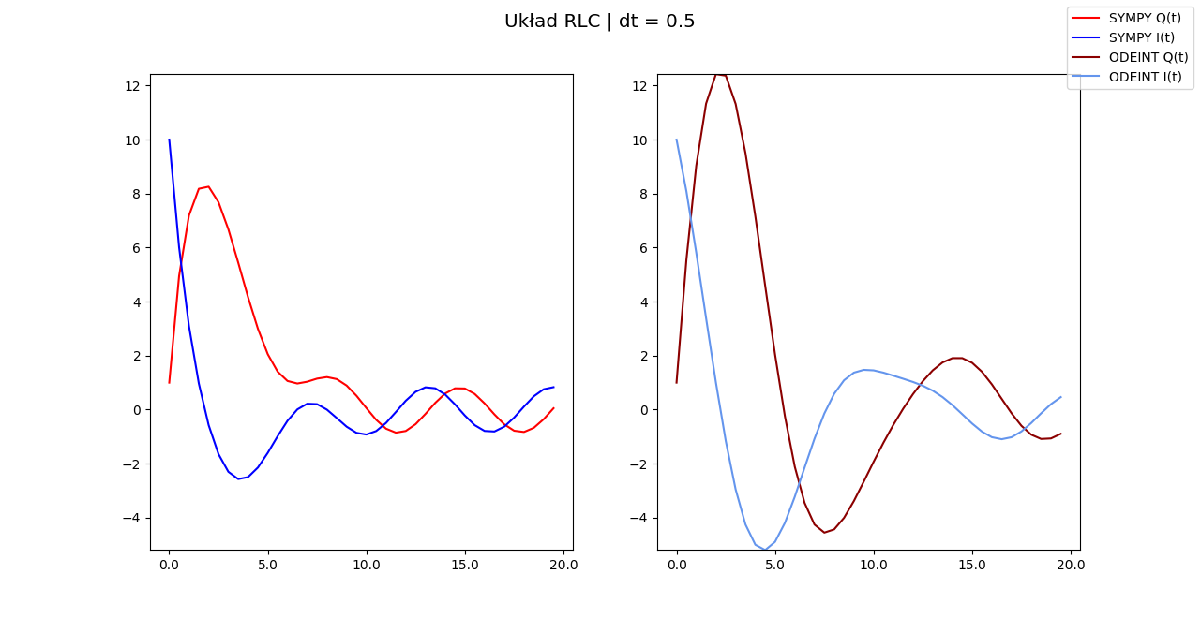

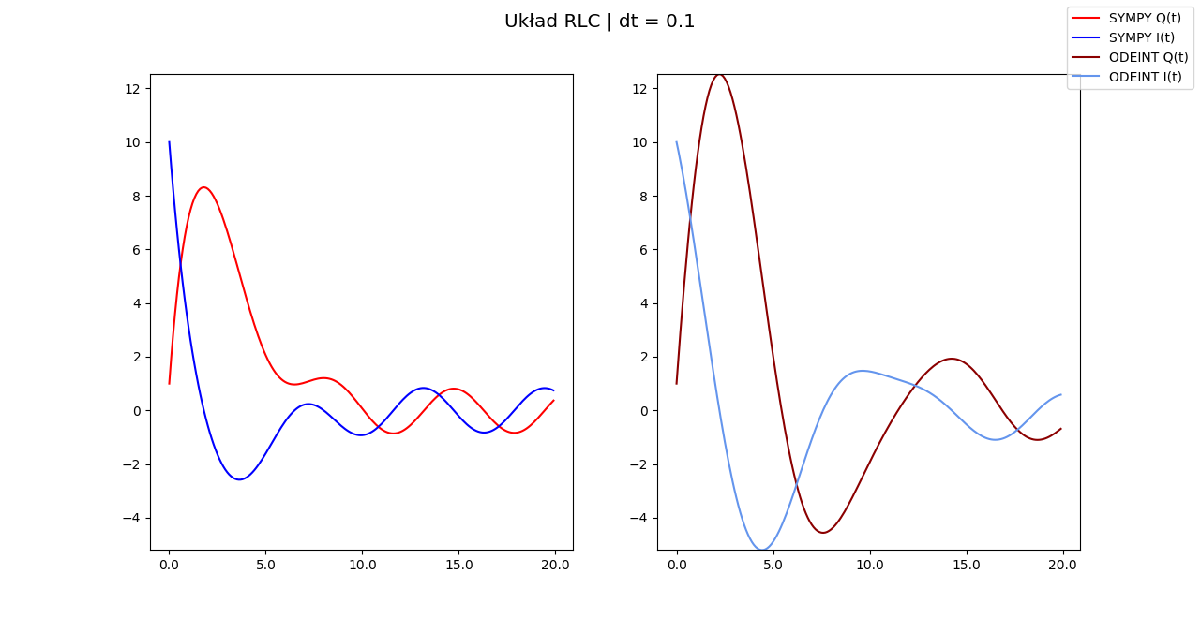

`Figure 7: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

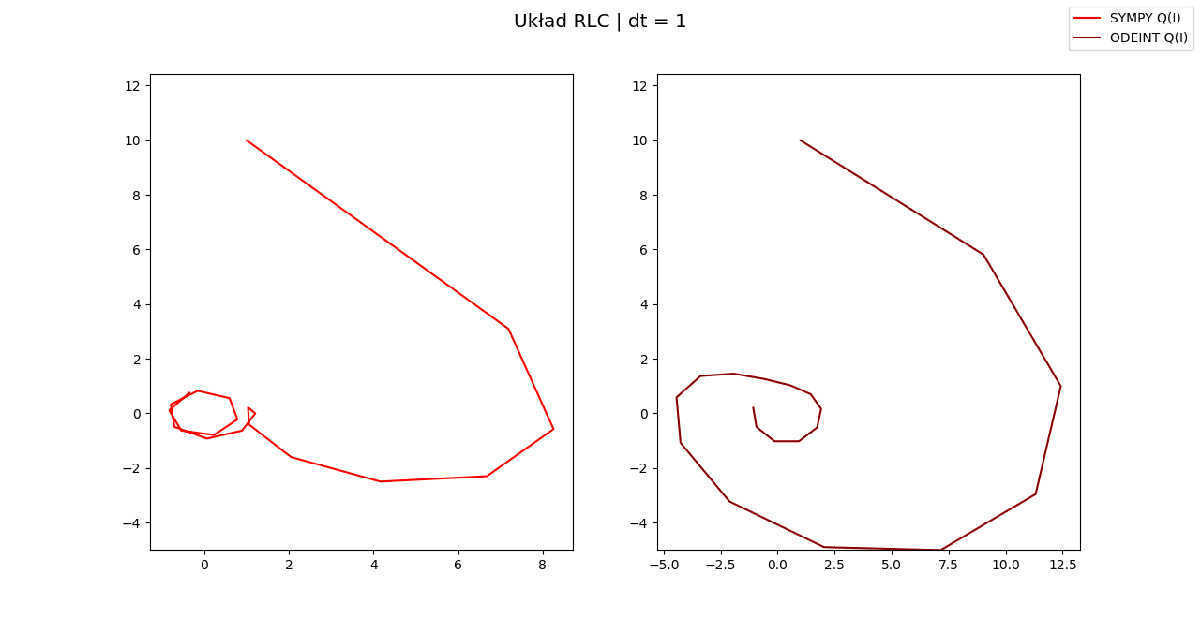

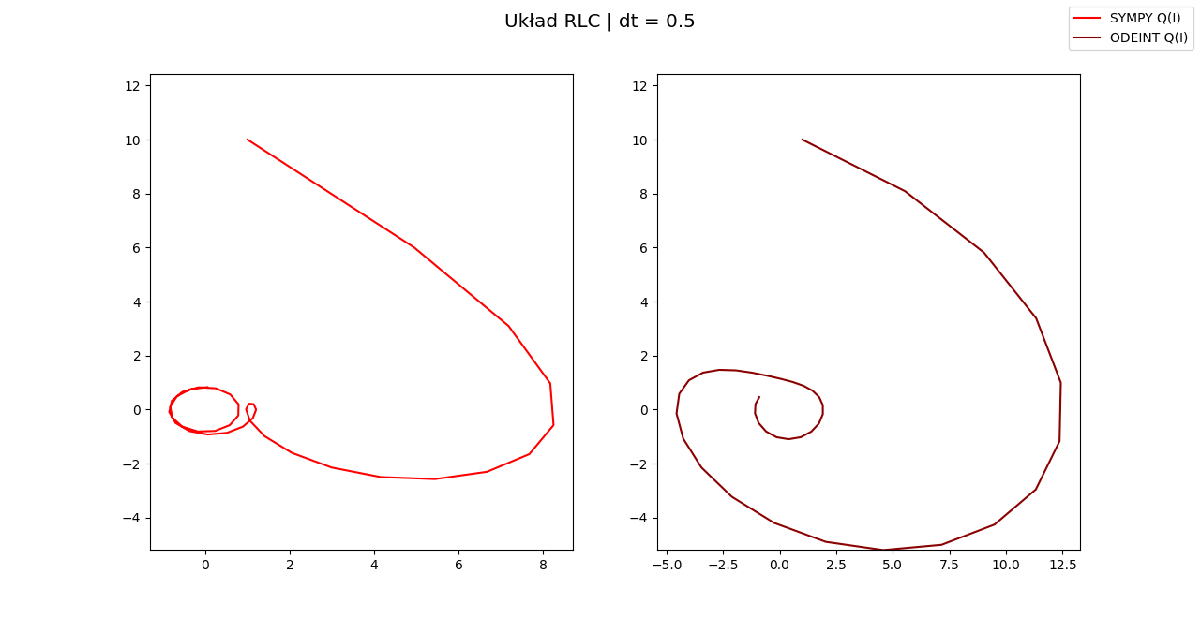

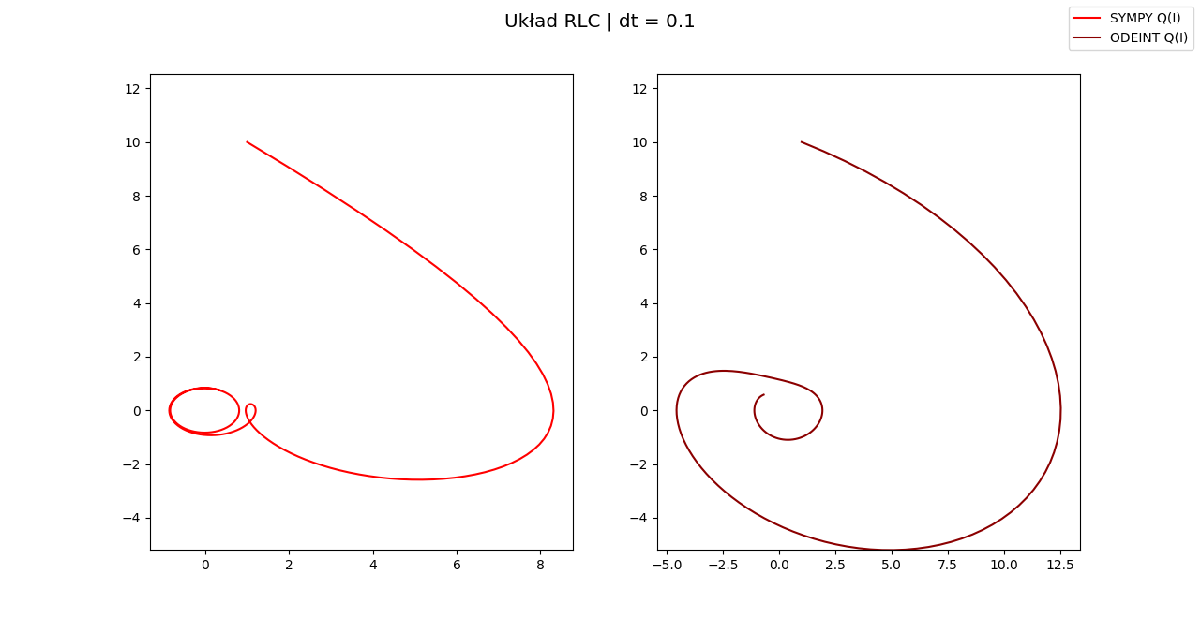

`Figure 8: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

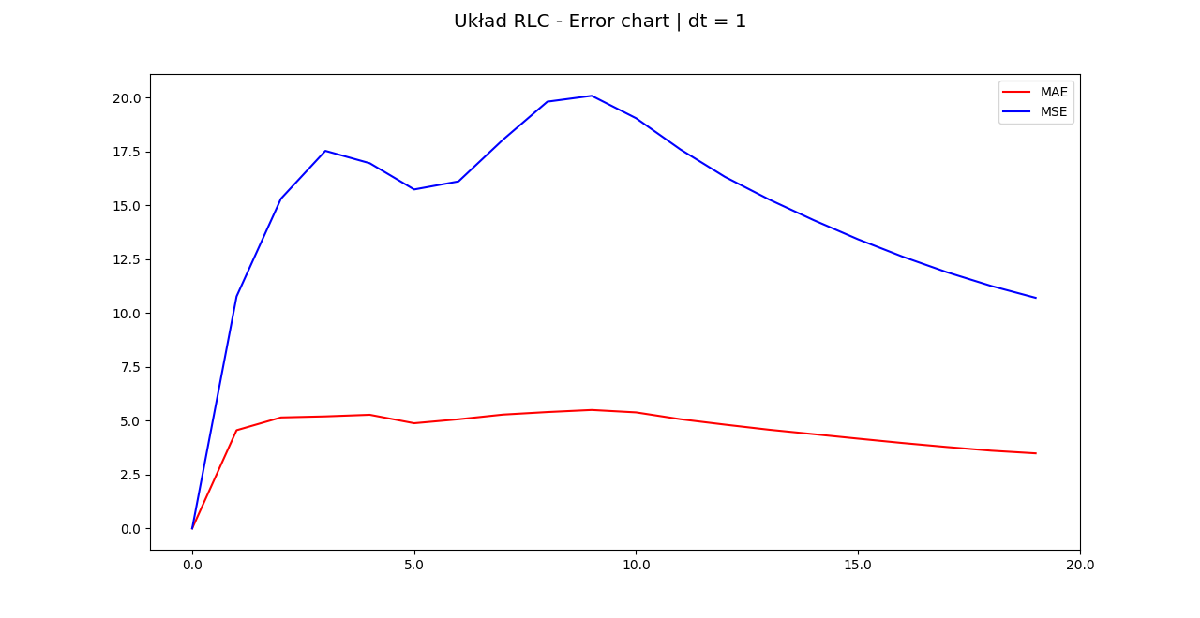

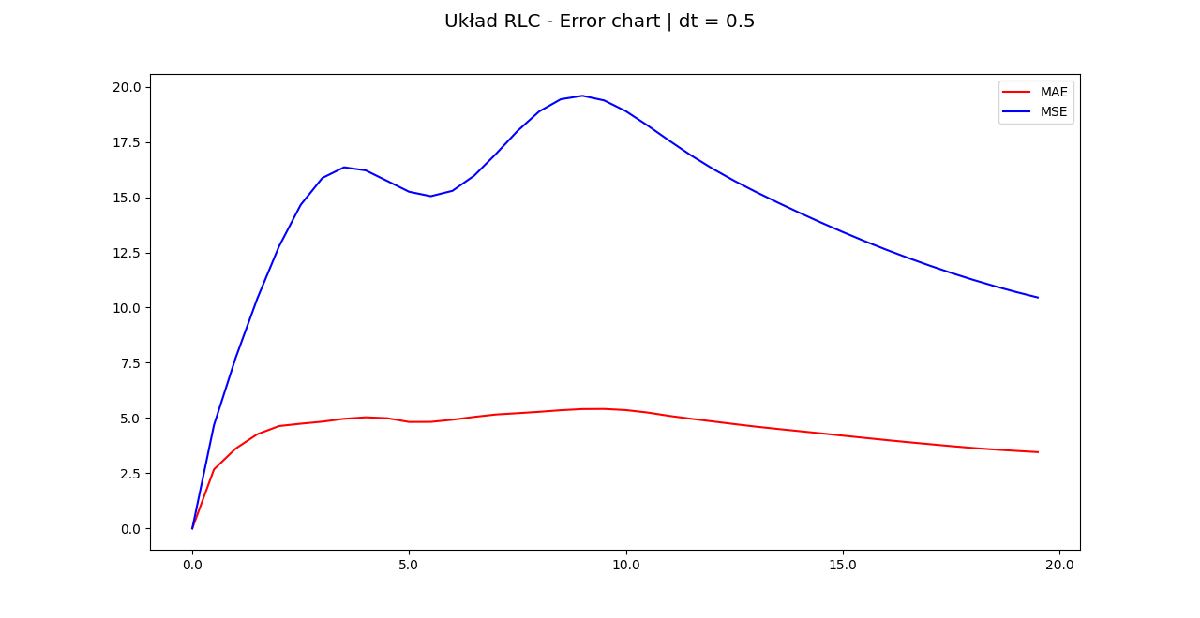

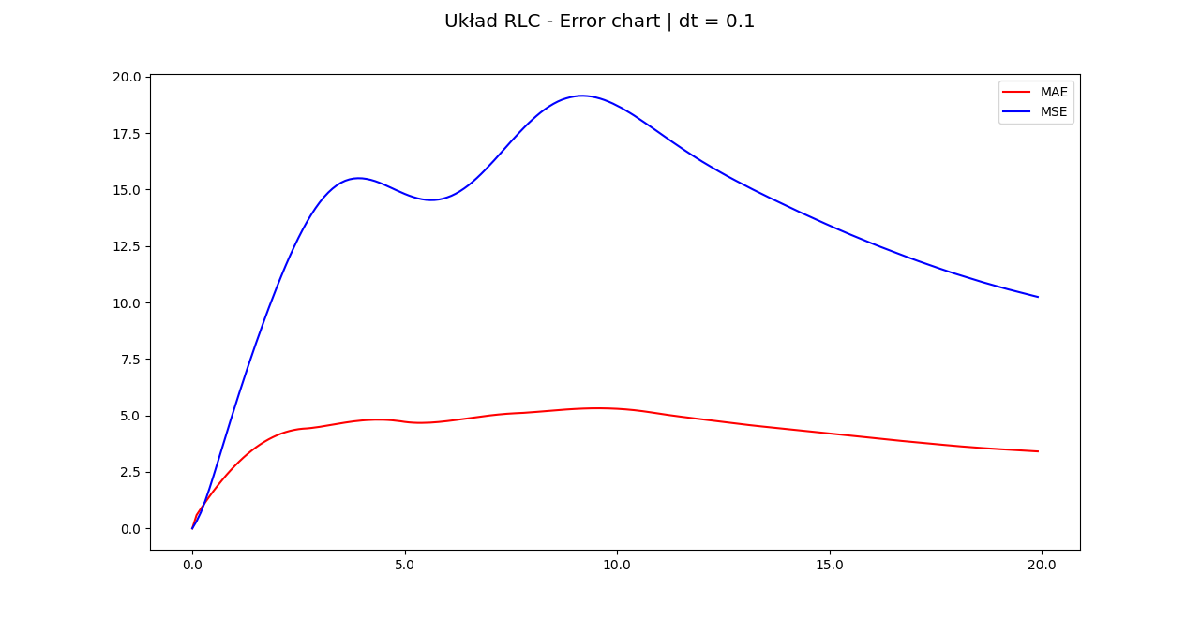

`Figure 9: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  10.165,  MAE:  3.3094

- `dt = 0.5`

MSE:  10.196,  MAE:  3.3683

- `dt = 0.1`

 MSE:  10.208,  MAE:  3.3887

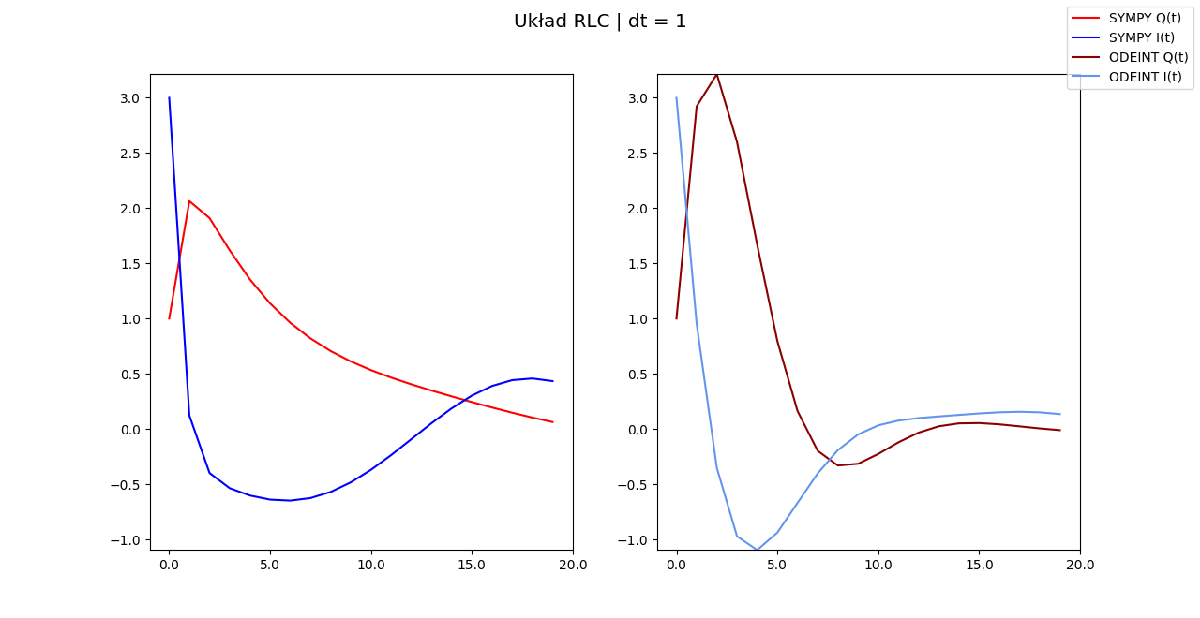

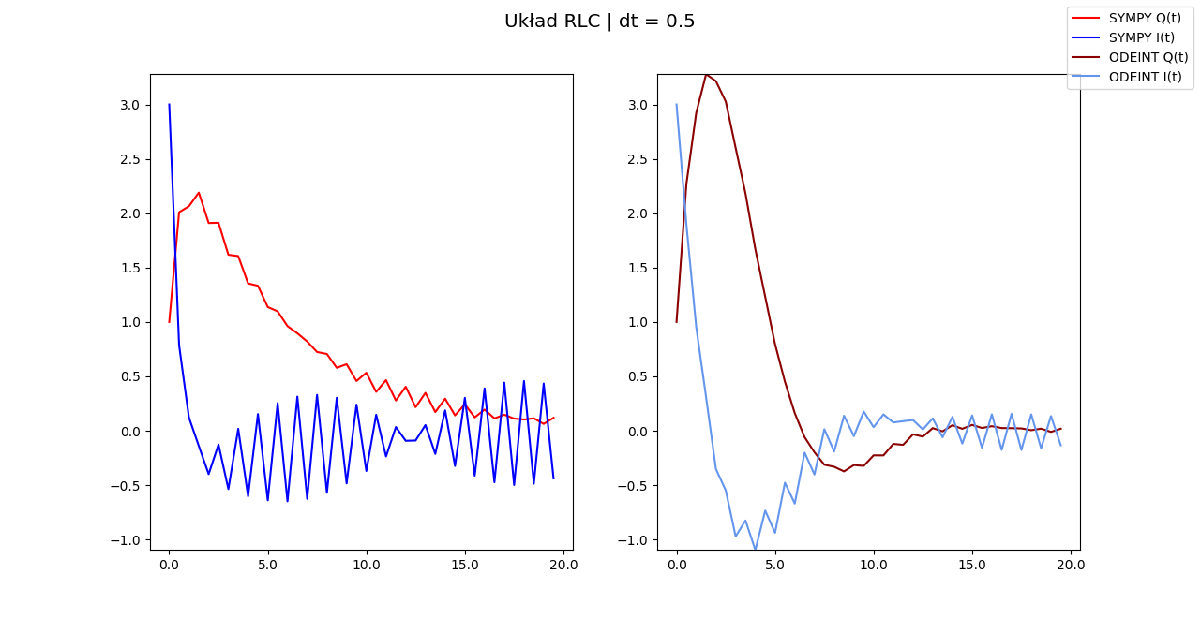

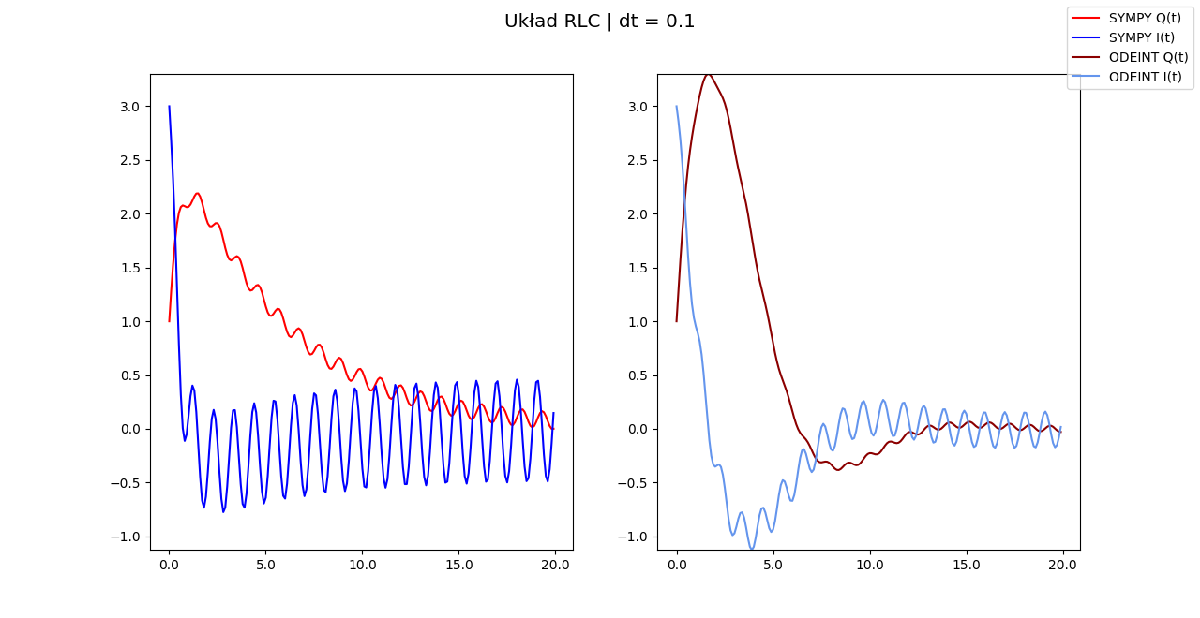

`Figure 10: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

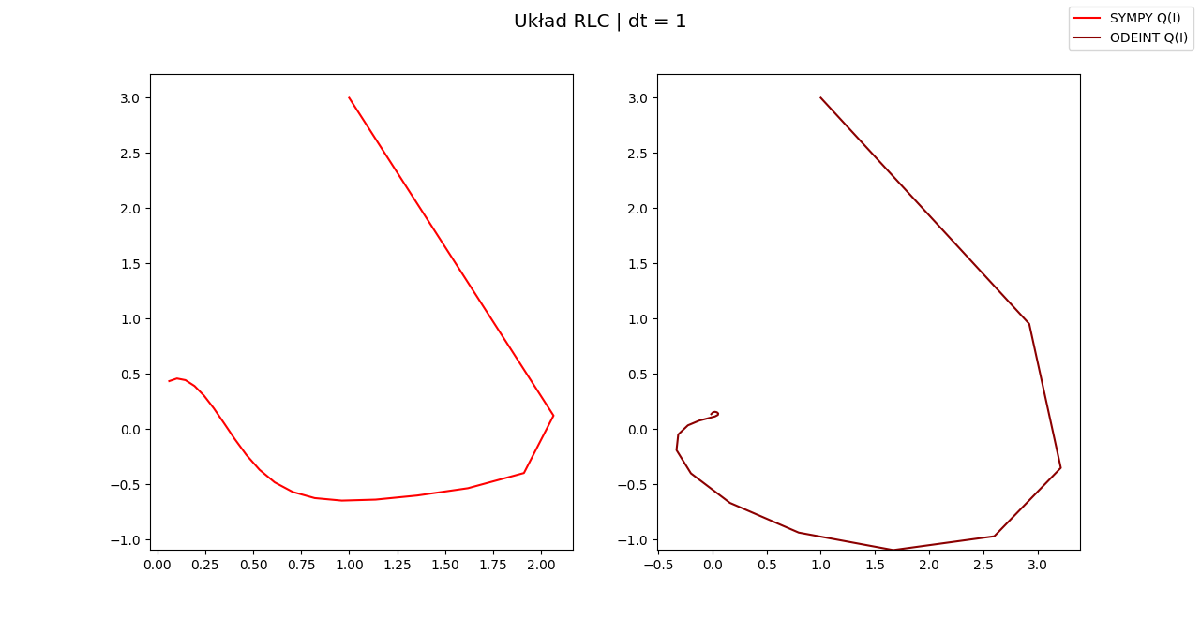

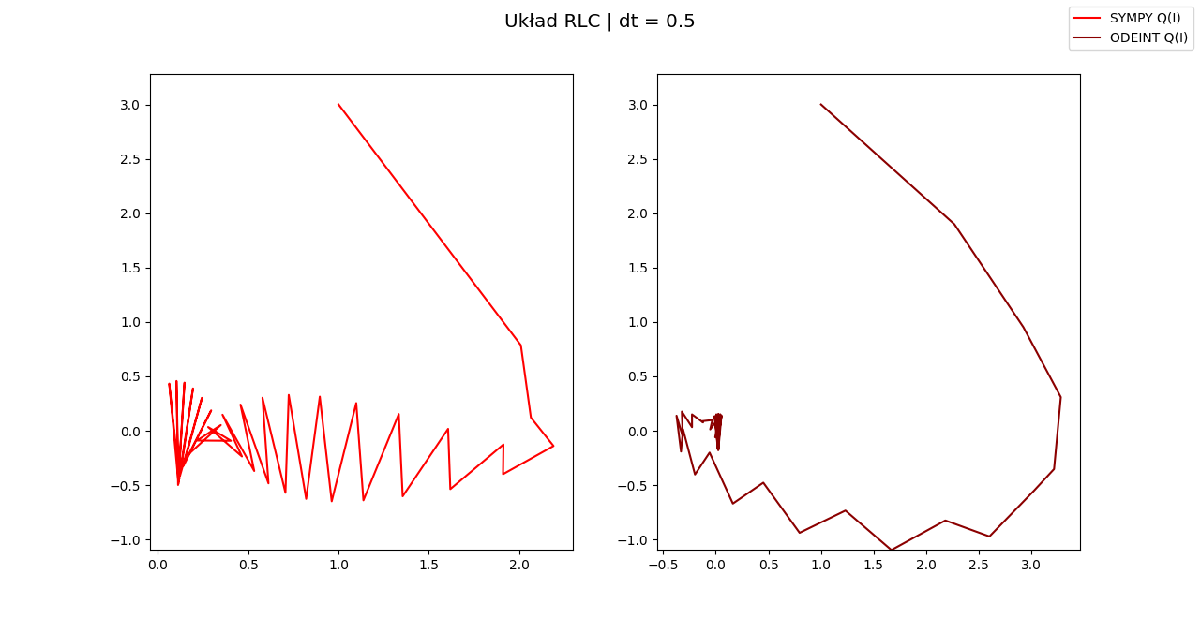

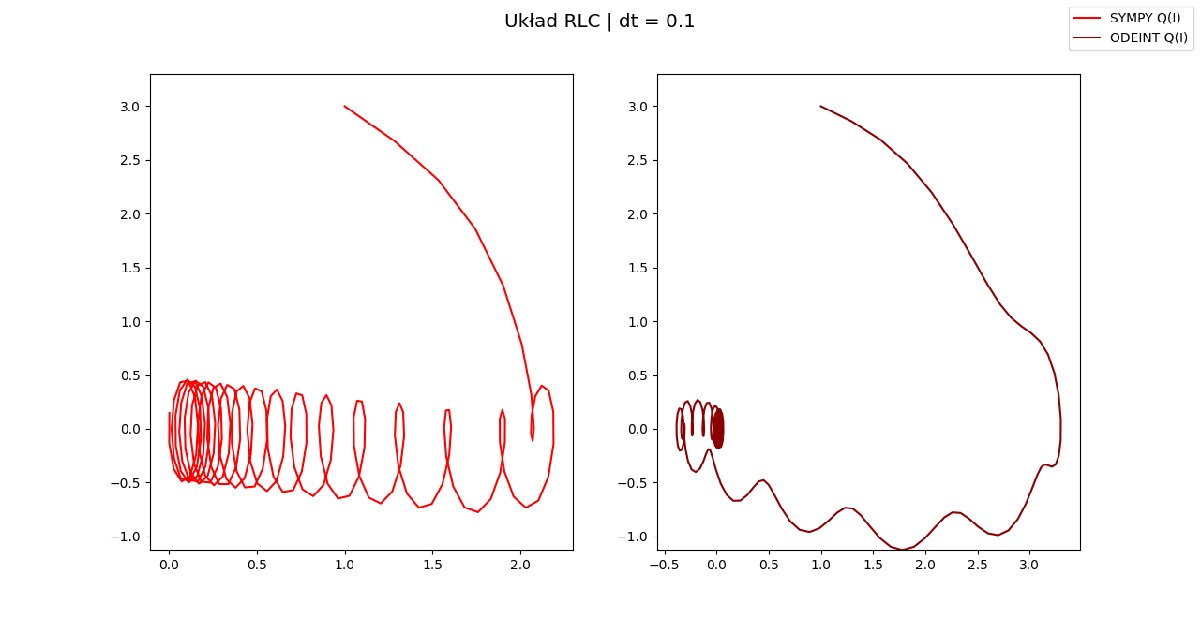

`Figure 11: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

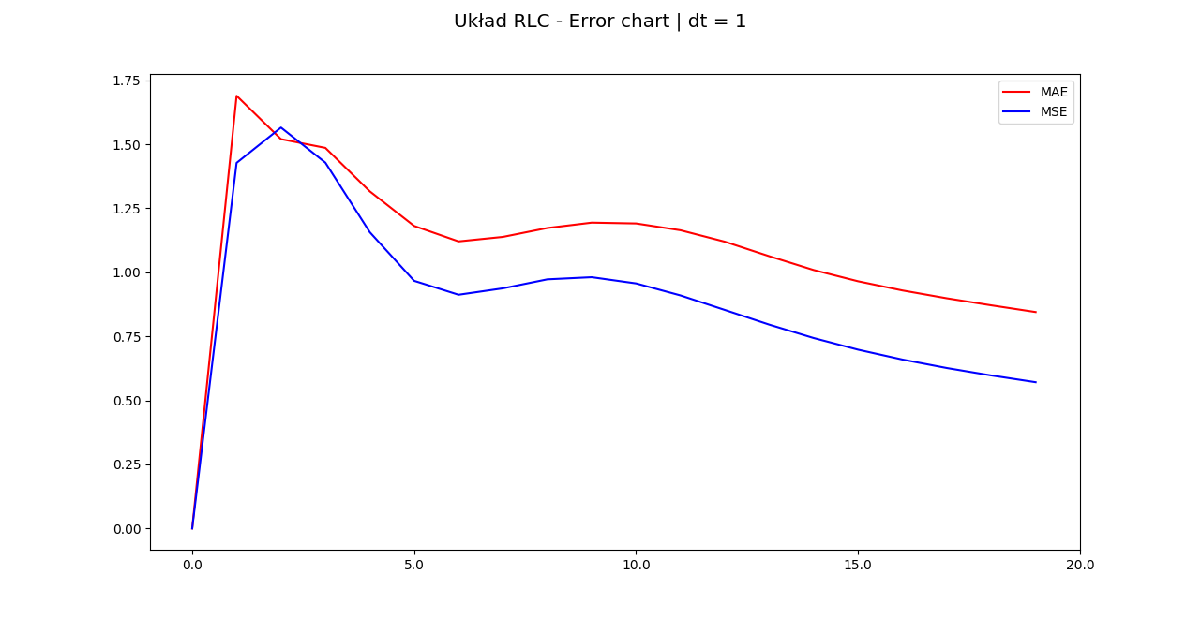

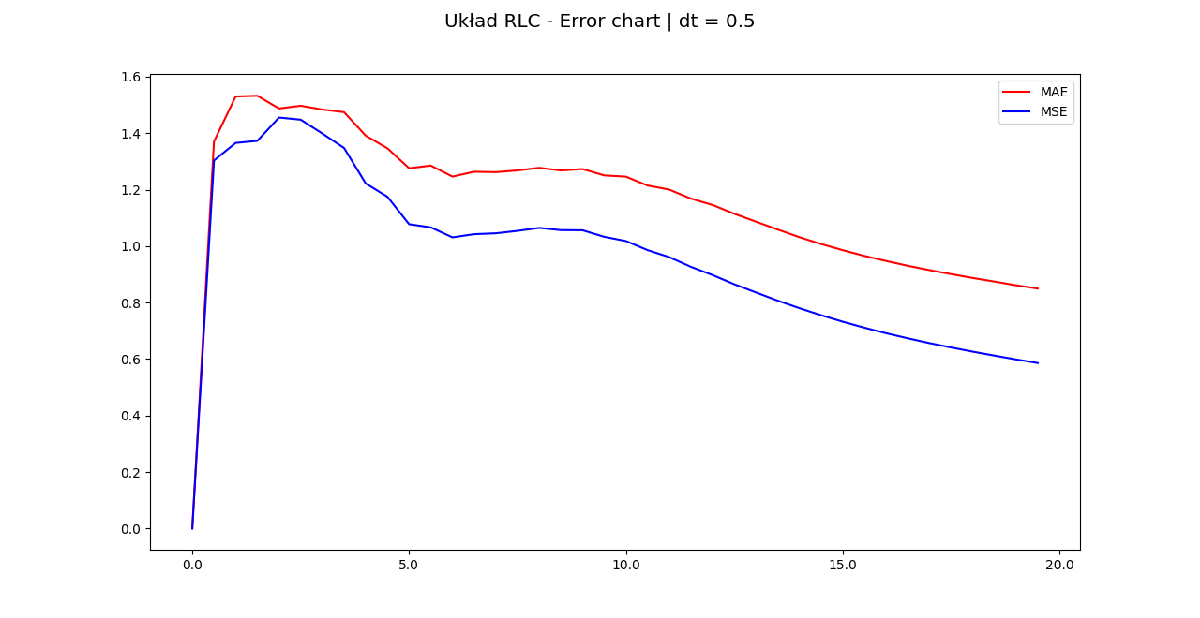

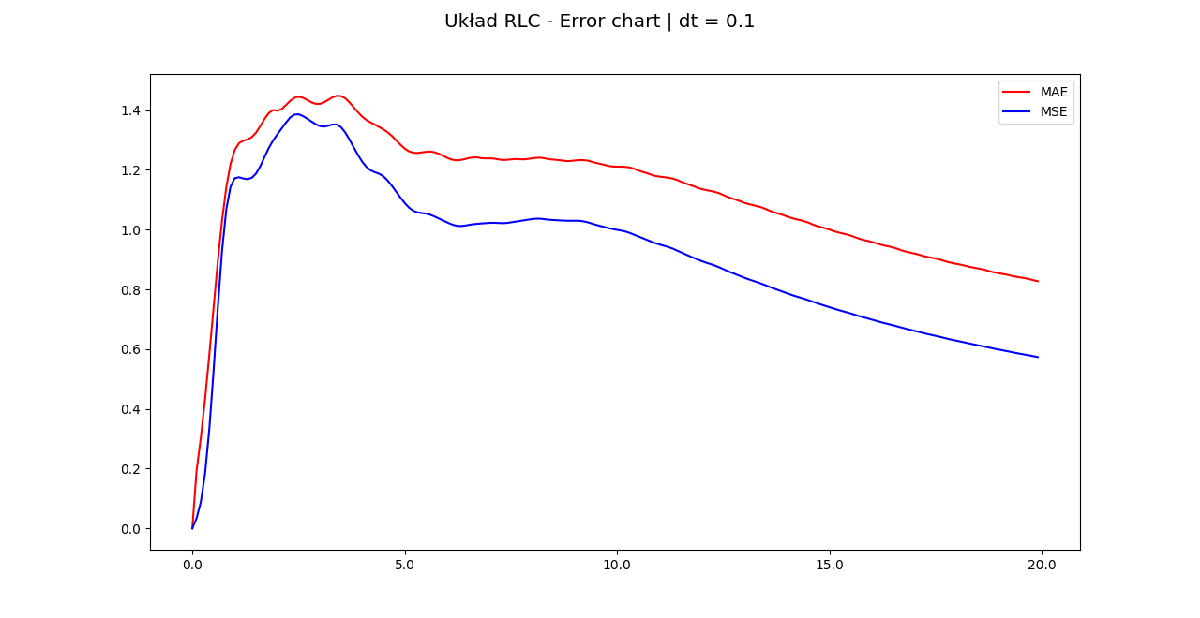

`Figure 12: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  0.54235,  MAE:  0.80282

- `dt = 0.5`

MSE:  0.57134,  MAE:  0.82821

- `dt = 0.1`

MSE:  0.57044,  MAE:  0.82354

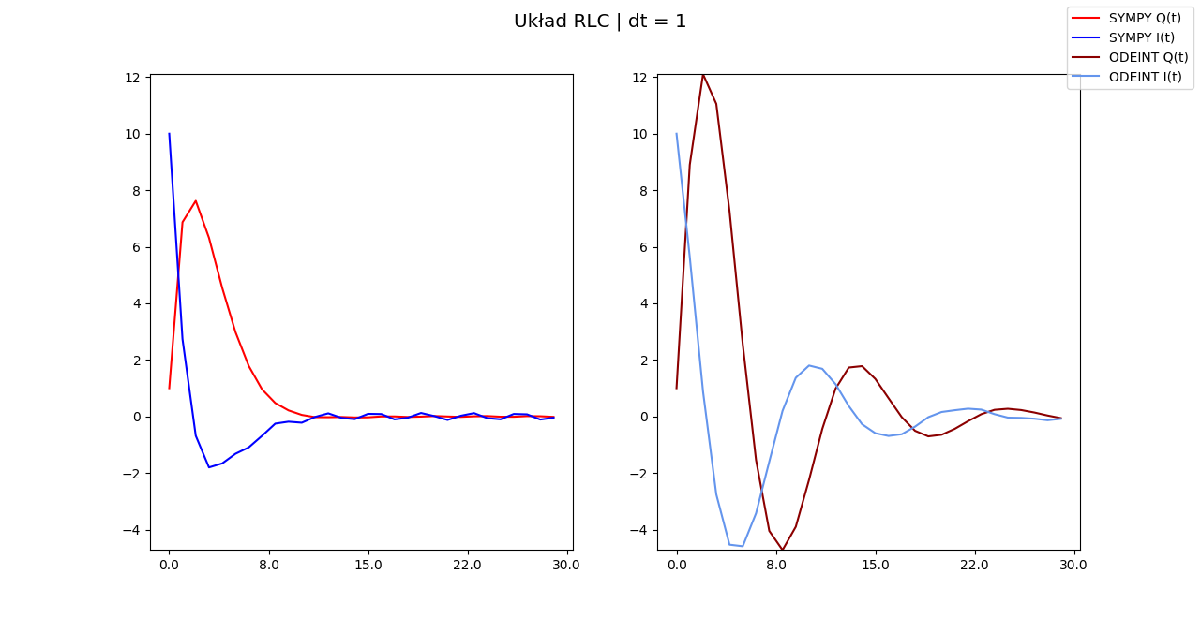

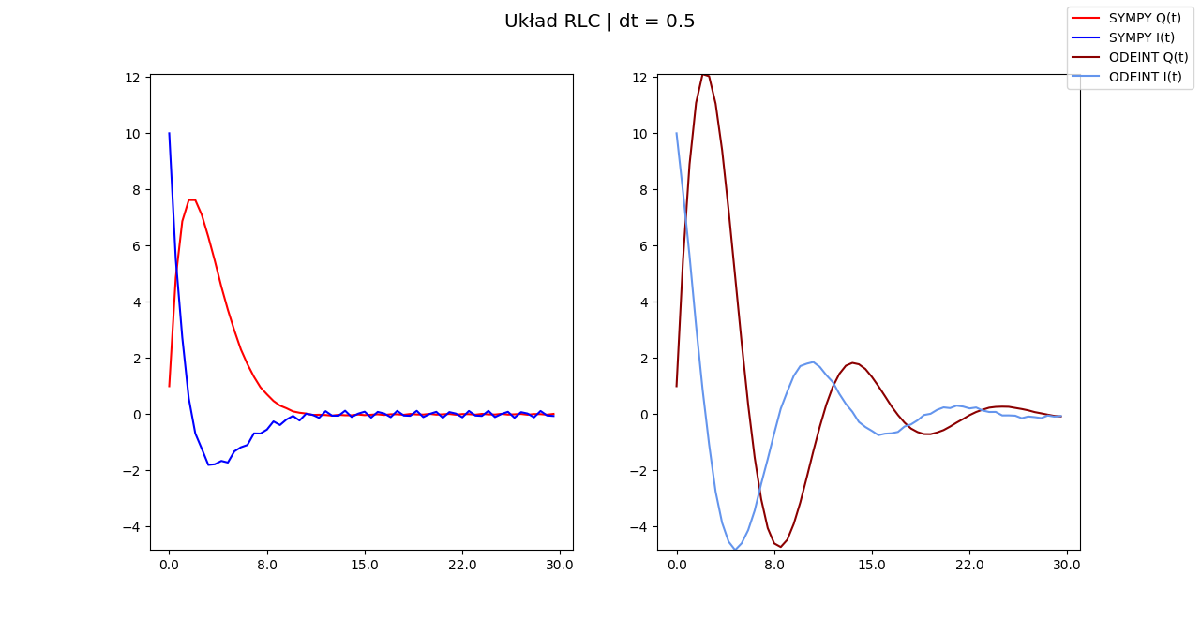

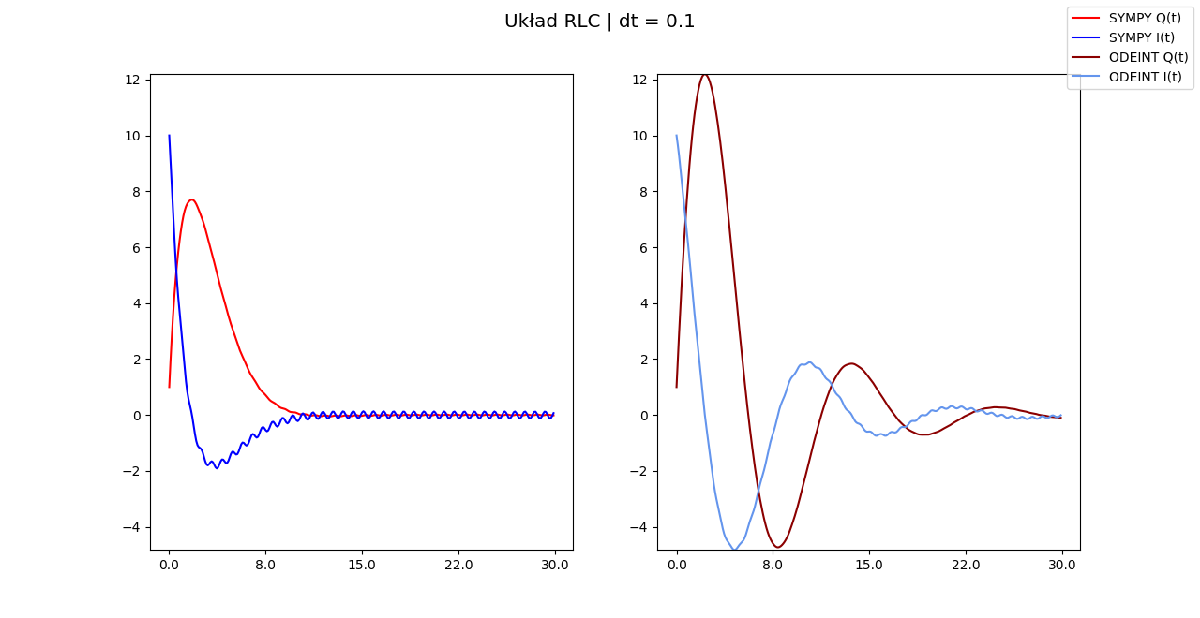

`Figure 13: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

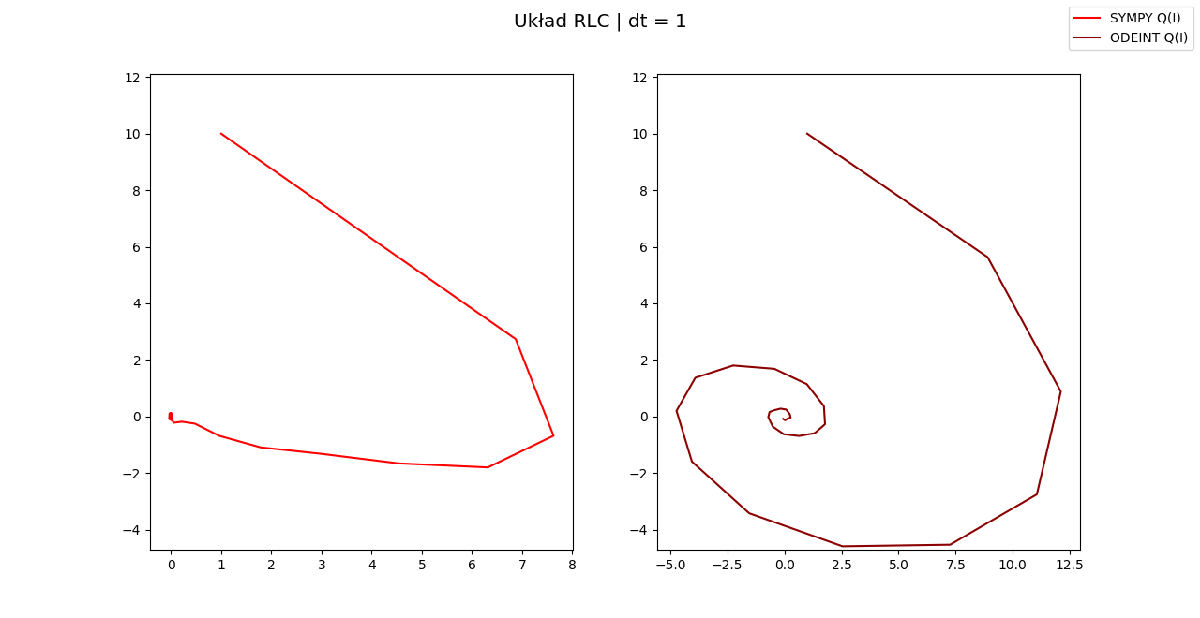

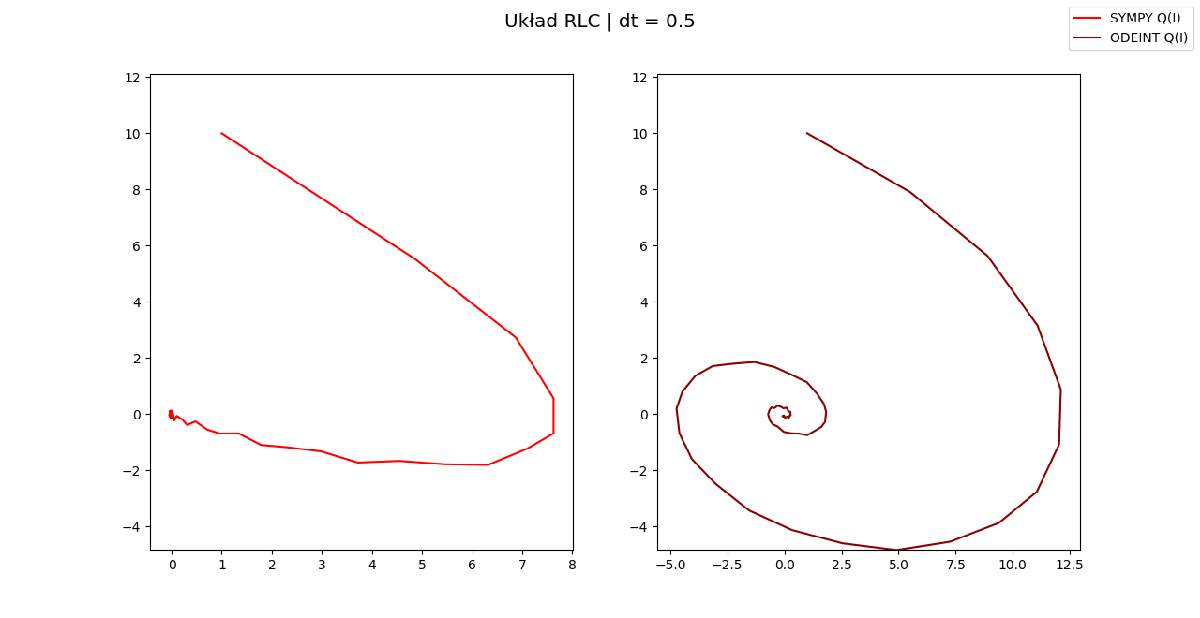

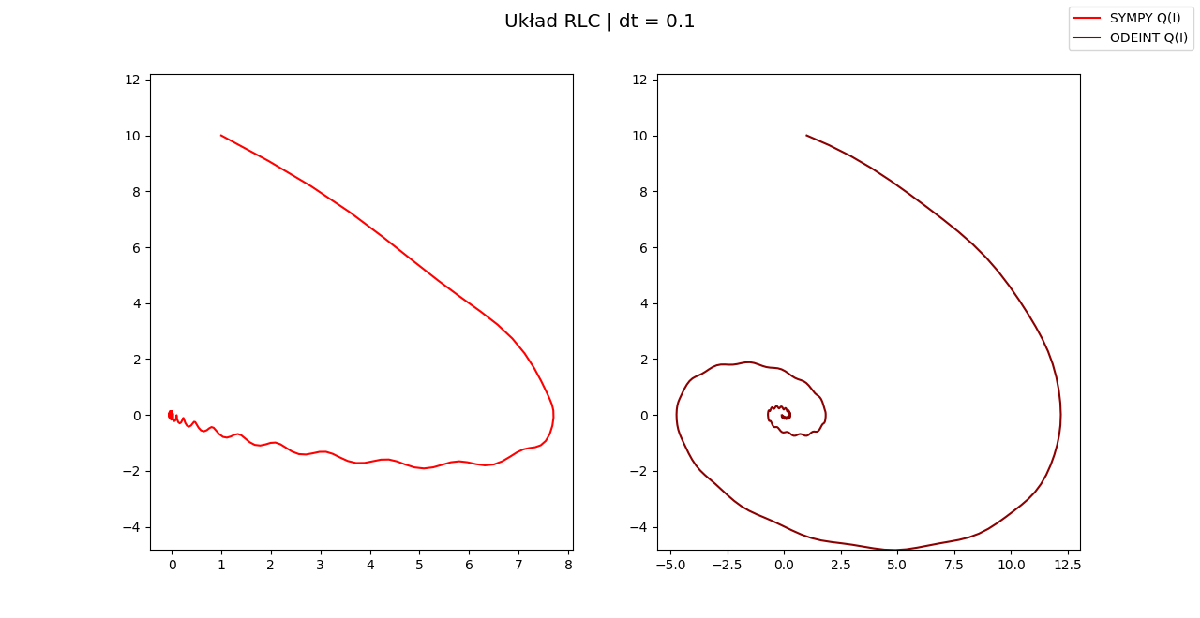

`Figure 14: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

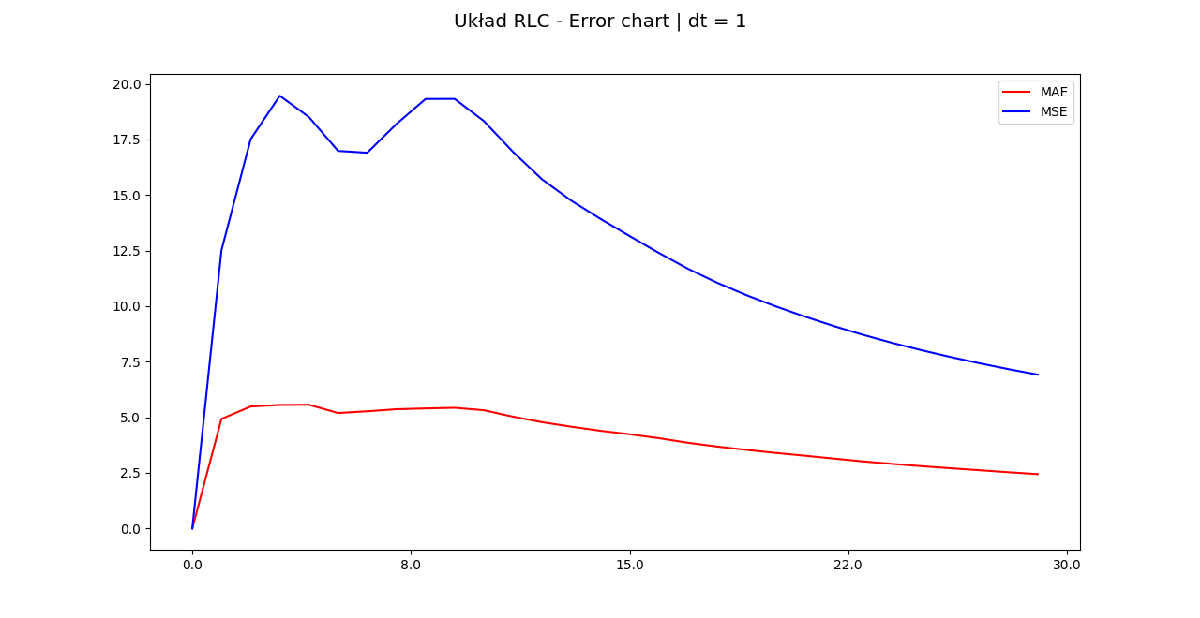

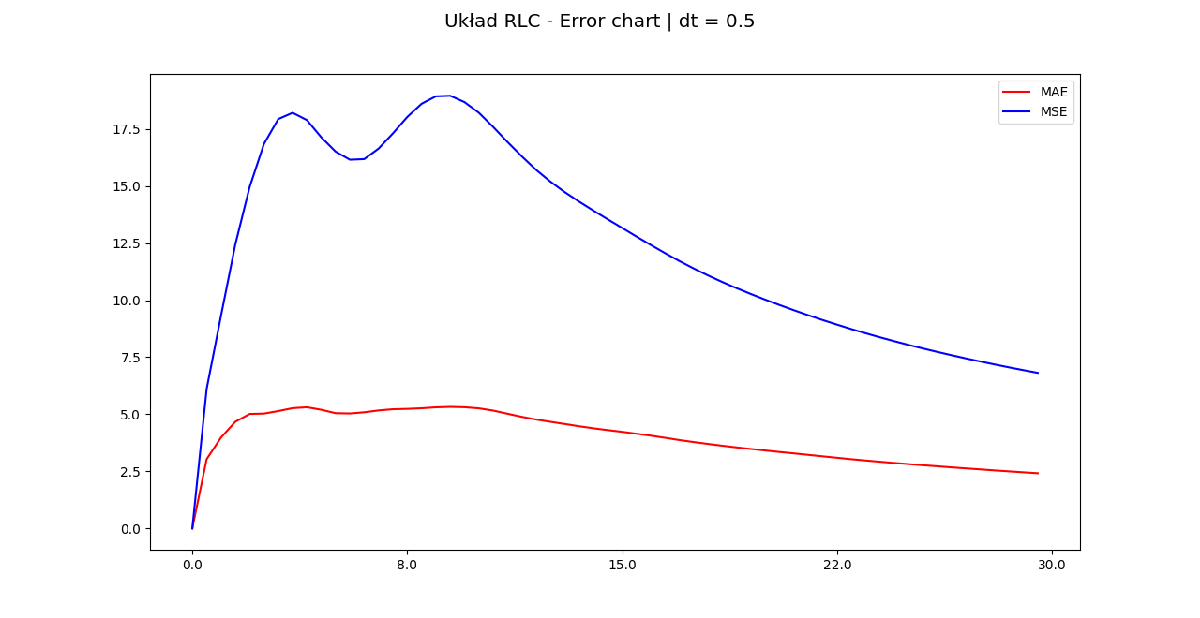

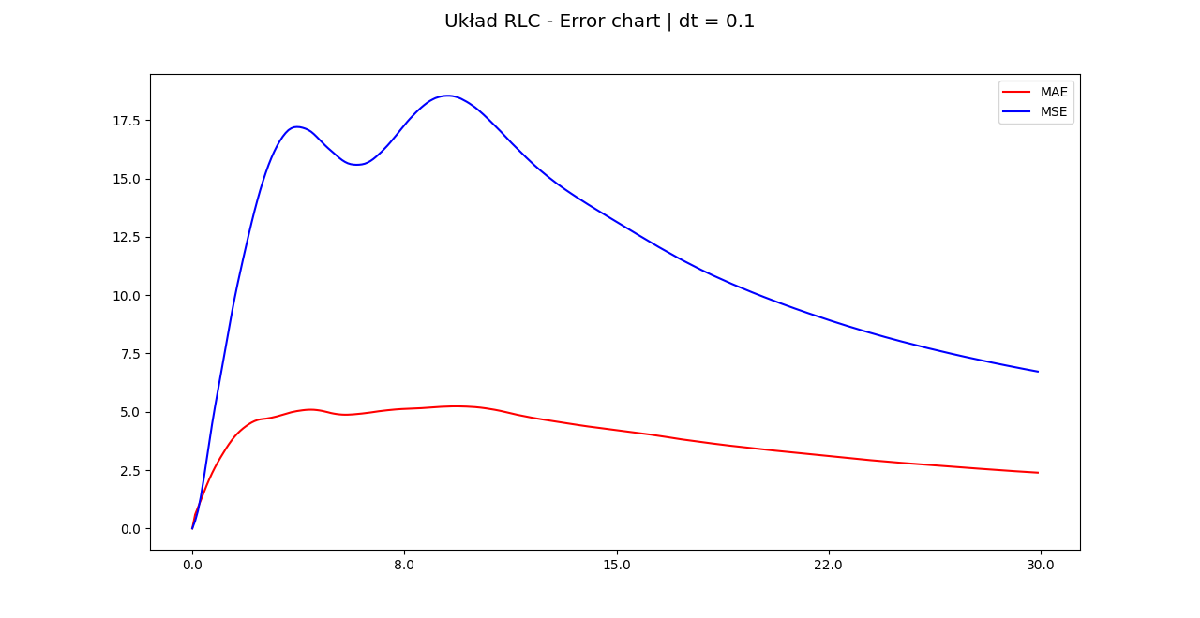

`Figure 15: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  6.6868,  MAE:  2.3618

- `dt = 0.5`

MSE:  6.7092,  MAE:  2.3761

- `dt = 0.1`

MSE:  6.7096,  MAE:  2.3825

#### `WNIOSKI`

`Realizacja modelu za pomocą modułu sympy umożliwia uzyskanie dokładnego, analitycznego rozwiązania układu równań różniczkowych opisujące model obwodu. Z koleji realizacja modelu metodą scipy.integrate.odeint pozwala na aproksymację numeryczną ewolucji układu. Analityczne rozwiązanie jest dokładniejsze od rozwiązania za otrzymanego za pomocą odeint, ponieważ w pierwszej metodzie dokonujemy dyskretyzacji, a zatem obserwujemy obwód w dyskretnych chwilach i jedyny występujący błąd to ten związany z dokładnością aproksymacji liczbowej, natomiast drugi sposób konstruuje następne obserwacje rekurencyjnie na podstawie poprzednich, przez co błąd związany z dokładnością nakłada się na siebie co każdą obserwację. Możemy to zauważyć obserwując średni błąd bezwzględy lub kwadratowy. Dla zmniejszającego się dt (kroku czasowego) spodziewalibyśmy się zmniejszenia błędów aproksymacji (ponieważ zwiększamy rozdzielczość), natomiast obserwujemy wynik przeciwny - dla zmniejszania kroku czasowego zwiększa się średni błąd aproksymacji, ponieważ algorytm rozwiązujący układ rówanń różniczkowych wykonuje więcej kroków, a zatem mamy doczynienia z większą ilością nałożonych błędów z każdą iteracją.`